## definition of constants

clear;
clc;

Jex=0.63;
Jey=0.69;
Jez=0.86;
Jlx=0.53;
Jly=0.15;
Jlz=0.4;
Jax=3.07;
Jay=4.13;
Jaz=2.61;
Rm=1.22;
Lm=5.13;
Km=0.363;
Kt=0.31;
n=50; %this is n_e from the paper
%n_a=150; not being used rn
beta=deg2rad(35);
max_time=100;

global time_prior ...
        integral_v1 integral_v2 integral_v3 ...
        error_v1_prior error_v2_prior error_v3_prior;
time_prior = 0; 
integral_v1 = 0;
integral_v2 = 0;
integral_v3 = 0;
error_v1_prior = 0;
error_v2_prior = 0;
error_v3_prior = 0;  

## ode45 and plotting

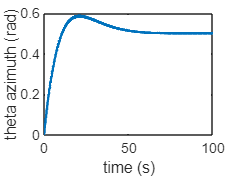

tspan=[0 max_time];
x_init=transpose([0 0 0 0 0 0 0 0 0]);
[t, x]=ode45(@(t, x) odefcn(t, x), tspan, x_init);
y_v1=x(:, 1);
y_v2=x(:, 4);
y_v3=x(:, 7);

graph_v1=plot(t, y_v1);
xlabel('time (s)');
ylabel('theta azimuth (rad)');
set(graph_v1, 'linewidth', 1.5);

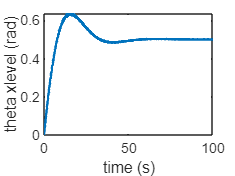


graph_v2=plot(t, y_v2);
xlabel('time (s)');
ylabel('theta xlevel (rad)');
set(graph_v2, 'linewidth', 1.5);

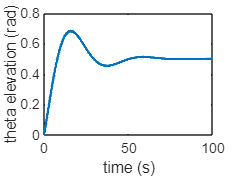


graph_v3=plot(t, y_v3);
xlabel('time (s)');
ylabel('theta elevation (rad)');
set(graph_v3, 'linewidth', 1.5);

## function definitions

function dxdt = odefcn(t, x)
    Jex=0.63;
    Jey=0.69;
    Jez=0.86;
    Jlx=0.53;
    Jly=0.15;
    Jlz=0.4;
    Jax=3.07;
    Jay=4.13;
    Jaz=2.61;
    Rm=1.22;
    Lm=5.13;
    Km=0.363;
    Kt=0.31;
    n=50; %this is n_e from the paper
    %n_a=150; not being used rn
    beta=deg2rad(35);

    global time_prior ...
           error_v1_prior error_v2_prior error_v3_prior;

    %state space definition
    %azimuth axis
    v1=x(1, 1); %angular displacement
    v1_dot=x(2, 1); %angular velocity
    ia=x(3, 1); %currrent
    %xlevel axis
    v2=x(4, 1); %angular displacement
    v2_dot=x(5, 1); %angular velocity
    il=x(6, 1); %currrent
    %elevation axis
    v3=x(7, 1); %angular displacement
    v3_dot=x(8, 1); %angular velocity
    ie=x(9, 1); %currrent

    %definition of torques
    Mey=n*Kt*ie;
    Mlz=n*Kt*il;
    Maz=n*Kt*ia;

    %definition of total inertias
    JLz=Jlz+(cos(v3)^2)*Jex+(sin(v3)^2)*Jez;
    JAz=Jaz+(cos(v2)^2)*(cos(beta)^2)*(Jlx+(sin(v3)^2)*Jex+(cos(v3)^2)*Jez) ...
         +2*cos(v2)*sin(v3)*cos(v3)*sin(beta)*cos(beta)*(Jex-Jez) ...
         +(sin(v2)^2)*(cos(beta)^2)*(Jly+Jey) ...
         +(sin(beta)^2)*(Jlz+(cos(v3)^2)*Jex+(sin(v3)^2)*Jez);

    v1_desired=0.5;
    error_v1=v1_desired-v1; %v1 is actual value
    error_v1_dot=-v1_dot;
    Va=control_azimuth(t, error_v1, time_prior, error_v1_dot); %voltage of azimuth axis
    %clipping of voltage
    Va=clip(Va, 10, -10);

    v2_desired=0.5;
    error_v2=v2_desired-v2; %v2 is actual value
    error_v2_dot=-v2_dot;
    Vl=control_xlevel(t, error_v2, time_prior, error_v2_dot); %voltage of xlevel axis
    %clipping of voltage
    Vl=clip(Vl, 10, -10);

    v3_desired=0.5;
    error_v3=v3_desired-v3; %v3 is actual value
    error_v3_dot=-v3_dot;
    Ve=control_elevation(t, error_v3, time_prior, error_v3_dot); %voltage of elevation axis
    %clipping of voltage
    Ve=clip(Ve, 10, -10);

    error_v1_prior=error_v1;
    error_v2_prior=error_v2;
    error_v3_prior=error_v3;
    time_prior=t;


    %differential equations for ode45
    dxdt=zeros(9, 1);

    dxdt(1, 1) = v1_dot;
    dxdt(2, 1) = Maz/JAz; %v1_double_dot
    dxdt(3, 1)= (Va-Rm*ia-Km*n*v1_dot)/Lm; %ia_dot
    
    dxdt(4, 1) = v2_dot;
    dxdt(5, 1) = (Mlz/JLz)-dxdt(2, 1)*sin(beta); %v2_double_dot
    dxdt(6, 1) = (Vl-Rm*il-Km*n*v2_dot)/Lm; %il_dot

    dxdt(7, 1) = v3_dot;
    dxdt(8, 1) = (Mey/Jey)+(v1_dot*cos(beta)*cos(v2)*v2_dot) ...
                 +(dxdt(2, 1)*cos(beta)*sin(v2)); %v3_double_dot
    dxdt(9, 1) = (Ve-Rm*ie-Km*n*v3_dot)/Lm; %ie_dot
end

function u = control_azimuth(t, error, time_prior, error_dot)
    %PID gains
    kp=35; %21
    ki=2; %10
    kd=180; %60
    bias=0; %0.32 for theta_desired=0.5
    
    global integral_v1;
    integral_v1=integral_v1+ki*error*(t-time_prior);
    u=kp*error+integral_v1+kd*error_dot+bias;
end

function u = control_xlevel(t, error, time_prior, error_dot)
    %PID gains
    kp=15; %21
    ki=2; %10
    kd=70; %60
    bias=0; %0.32 for theta_desired=0.5
    
    global integral_v2;
    integral_v2=integral_v2+ki*error*(t-time_prior);
    u=kp*error+integral_v2+kd*error_dot+bias;
end

function u = control_elevation(t, error, time_prior, error_dot)
    %PID gains
    kp=10; %21
    ki=2; %10
    kd=60; %60
    bias=0; %0.32 for theta_desired=0.5
    
    global integral_v3;
    integral_v3=integral_v3+ki*error*(t-time_prior);
    u=kp*error+integral_v3+kd*error_dot+bias;
end

function val = clip(val, upper_bound, lower_bound)
   if val>upper_bound
        val=upper_bound;
    end
    if val<lower_bound
        val=lower_bound;
    end 
end



